% QUESTION 1
% Given the system of linear equations 
%  x + 2y - 3z = 5
%  -3x - y + z = -8 
%  x - y + z = 0 

A = [1,2,-3; -3 -1 1; 1 -1 1]

A =      1     2    -3
    -3    -1     1
     1    -1     1


B = [5;-8;0]

B =      5
    -8
     0



% Define the  for a matrix vector: Ax = B
% This implies x = B\A it works for a rectangular and square matrix

x = inv(A)*B

x =     2.0000
    3.0000
    1.0000



% QUESTION 2: Basic Operations 
% Rank of a matrix: Number of non zero rows of a matrix after RREF 
mat = [1 0 0; 0 1 0; 0 0 1]

mat =      1     0     0
     0     1     0
     0     0     1


r = rank(mat)

r = 3


% Determinant of a matrix 
 d = det(mat)

d = 1


% Matrix
 XYZ = [1 2 3; 4 5 6; 7 8 9]

XYZ =      1     2     3
     4     5     6
     7     8     9


E = inv(XYZ) % 1/det times adjoint 

E = 1.0e+16 *

   -0.4504    0.9007   -0.4504
    0.9007   -1.8014    0.9007
   -0.4504    0.9007   -0.4504



% Condition Number 
ABC = [1 7 3; 4 -2 6; 0 8 -1]

ABC =      1     7     3
     4    -2     6
     0     8    -1


c = cond(ABC) % Matrix nearly singular (det=0) for poor condition

c = 11.8267

t = rcond(ABC) 

t = 0.0546



% Matrix Decomposition 
% 1. Eigen value decomposition 
x = [1 2 3; 6 5 4; 7 8 9] 

x =      1     2     3
     6     5     4
     7     8     9


[V,D] = eig(x) % Works if x is a square matrix 

V =    -0.2422   -0.5253    0.4082
   -0.4672    0.8000   -0.8165
   -0.8503   -0.2899    0.4082


D =    15.3899         0         0
         0   -0.3899         0
         0         0   -0.0000



% [V,D] = eig(A) produces a diagonal matrix D of eigenvalues and 
    % a full matrix V whose columns are the corresponding eigenvectors  
    % so that A*V = V*D. 

% 2. Singular value decomposition 
[U, S, V] = svd(x) % Works if x is a square matrix 

U =    -0.2108    0.5387   -0.8157
   -0.5137   -0.7710   -0.3765
   -0.8317    0.3396    0.4392


S =    16.7197         0         0
         0    2.3349         0
         0         0    0.0000


V =    -0.5451   -0.7322    0.4082
   -0.5768   -0.0258   -0.8165
   -0.6084    0.6806    0.4082



      % [U,S,V] = svd(A) produces a diagonal matrix S, of the same 
      % dimension as A and with nonnegative diagonal elements in
      % decreasing order, and unitary matrices U and V so that A = U*S*V'.

% 3. QR Decomposition 
[Q, R] = qr(x) 

Q =    -0.1078    0.5683   -0.8157
   -0.6470   -0.6631   -0.3765
   -0.7548    0.4872    0.4392


R =    -9.2736   -9.4893   -9.7049
         0    1.7186    3.4371
         0         0    0.0000


   % [Q,R] = qr(A) performs a qr decomposition on m-by-n matrix A such that
   % A = Q*R. The factor R is an m-by-n upper triangular matrix and Q is an
   %m-by-m unitary matrix.

% 4. LU Decomposition 
[L, U] = lu(x) 

L =     0.1429   -0.4615    1.0000
    0.8571    1.0000         0
    1.0000         0         0


U =     7.0000    8.0000    9.0000
         0   -1.8571   -3.7143
         0         0         0


      %[L,U] = lu(A) returns an upper triangular matrix in U and a permuted
      %lower triangular matrix in L, such that A = L*U. The input matrix A can
      %be full or sparse.

% 5. Cholesky Decomposition 
%R = chol(x) % Error, matrix must be positive definite 




% Polynomials 
% P =[2 3 0 5] represents 2x^3 + 3x^2 +5 

P = [1 3 2 0]; % P is a vector of length N (N to me is dimension of roots)

% For Roots of polynomial
r = roots(P) 

r =      0
    -2
    -1



% To get polynomial from roots back
f = [0 -2 -1];
P = poly(f)

P =      1     3     2     0



% To evaluate a polynomial at a point 
%Format: y0 = polyval(P, x0) P is the polynomial defined first,x0 is a
% root of polynomial. i.e at point x0, what is the corresponding value of y0
 
y0 = polyval(P, -2) % since -2 is a root, we should get zero

y0 = 0

y0 = polyval(P, 5) % 5 is not a root, we got remainder 210 

y0 = 210

x =      0    -2    -1     5


y =      0     0     0   210


Z =    -1.0000    0.0000    1.0000


x =     -1     0     1     2


y =     -4     2     2     8


Z =     2.0000   -3.0000    1.0000    2.0000


h =    -4.0000    2.0000    2.0000    8.0000


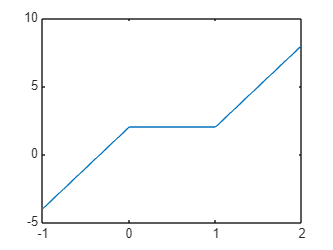

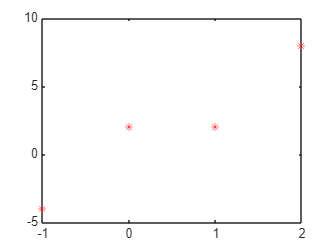

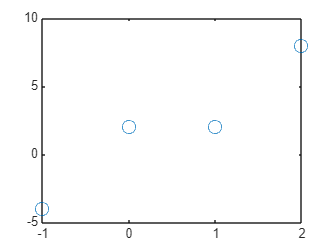

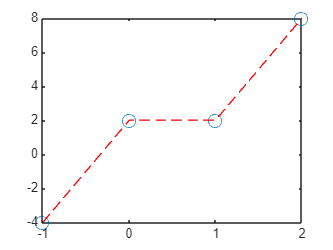

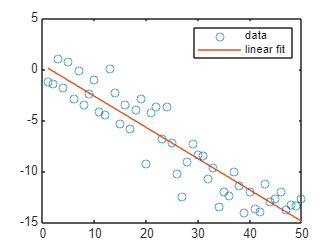

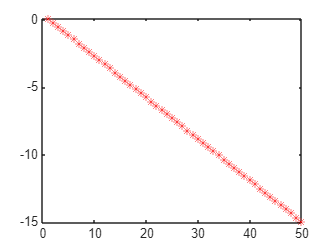



% To evaluate a polynomial at many points 
% First define x as a vector of many points 
x = [0 -2 -1 5]
y = polyval(P, x) % The roots gave zero while 5 gave 210 as required 
